clc
clear


% DataSet de audios
ads = audioDatastore("C:\Users\oscar\OneDrive\Escritorio\sp_seniales\datos","IncludeSubfolders",true , ...
    "FileExtensions",".wav","LabelSource","foldernames");

[adsTrain,adsTest] = splitEachLabel(ads,0.8);
adsTrain

adsTrain =   audioDatastore with properties:

                       Files: {
                              ' ...\Users\oscar\OneDrive\Escritorio\sp_seniales\datos\adrian\adrian1.wav';
                              ' ...\Users\oscar\OneDrive\Escritorio\sp_seniales\datos\adrian\adrian10.wav';
                              ' ...\oscar\OneDrive\Escritorio\sp_seniales\datos\adrian\adrian10_aug_0.wav'
                               ... and 1141 more
                              }
                     Folders: {
                              'C:\Users\oscar\OneDrive\Escritorio\sp_seniales\datos'
                              }
                      Labels: [adrian; adrian; adrian ... and 1141 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


trainDatastoreCount = countEachLabel(adsTrain)

trainDatastoreCount = 13×2 table
     Label      Count
    ________    _____

    adrian       88  
    alfredo      88  
    bruno        88  
    daniel       88  
    elias        88  
    emiliano     88  
    itzel        88  
    mariam       88  
    oscar        88  
    paola        88  
    paulo        88  
    yestli       88  
    yonathan     88  


adsTest

adsTest =   audioDatastore with properties:

                       Files: {
                              ' ...\Users\oscar\OneDrive\Escritorio\sp_seniales\datos\adrian\adrian8.wav';
                              ' ...\oscar\OneDrive\Escritorio\sp_seniales\datos\adrian\adrian8_aug_0.wav';
                              ' ...\oscar\OneDrive\Escritorio\sp_seniales\datos\adrian\adrian8_aug_1.wav'
                               ... and 283 more
                              }
                     Folders: {
                              'C:\Users\oscar\OneDrive\Escritorio\sp_seniales\datos'
                              }
                      Labels: [adrian; adrian; adrian ... and 283 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'
      SupportedOutputFormats: ["wav"    "flac"    "ogg"    "opus"    "mp4"    "m4a"]
         DefaultOutputFormat: "wav"


testDatastoreCount = countEachLabel(adsTest)

testDatastoreCount = 13×2 table
     Label      Count
    ________    _____

    adrian       22  
    alfredo      22  
    bruno        22  
    daniel       22  
    elias        22  
    emiliano     22  
    itzel        22  
    mariam       22  
    oscar        22  
    paola        22  
    paulo        22  
    yestli       22  
    yonathan     22  



[sampleTrain,dsInfo] = read(adsTrain);
sound(sampleTrain,dsInfo.SampleRate)
reset(adsTrain)


% Extracción de características

fs = dsInfo.SampleRate;
windowLength = round(0.03*fs);
overlapLength = round(0.025*fs);
afe = audioFeatureExtractor(SampleRate=fs, ...
    Window=hamming(windowLength,"periodic"),OverlapLength=overlapLength, ...
    zerocrossrate=true,shortTimeEnergy=true,pitch=true,mfcc=true);

featureMap = info(afe)

featureMap = struct with fields:
               mfcc: [1 2 3 4 5 6 7 8 9 10 11 12 13]
              pitch: 14
      zerocrossrate: 15
    shortTimeEnergy: 16



features = [];
labels = [];
energyThreshold = 0.65

energyThreshold = 0.6500

zcrThreshold = 0.45

zcrThreshold = 0.4500


keepLen = round(length(sampleTrain)/3);

while hasdata(adsTrain)
    [audioIn,dsInfo] = read(adsTrain);

    audioIn = audioIn(1:keepLen);

    feat = extract(afe,audioIn);
    isSpeech = feat(:,featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = feat(:,featureMap.zerocrossrate) < zcrThreshold;

    voicedSpeech = isSpeech & isVoiced;

    feat(~voicedSpeech,:) = [];
    feat(:,[featureMap.zerocrossrate,featureMap.shortTimeEnergy]) = [];
    label = repelem(dsInfo.Label,size(feat,1));
    
    features = [features;feat];
    labels = [labels,label];
end

M = mean(features,1);
S = std(features,[],1);
features = (features-M)./S;


% Entrenamiento de modelo kNN
trainedClassifier = fitcknn(features,labels, ...
    Distance="euclidean", ...
    NumNeighbors=5, ...
    DistanceWeight="squaredinverse", ...
    Standardize=false, ...
    ClassNames=unique(labels));

k = 10;
group = labels;
c = cvpartition(group,KFold=k); % 5-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,CVPartition=c);

validationAccuracy = 1 - kfoldLoss(partitionedModel,LossFun="ClassifError");
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 97.05%


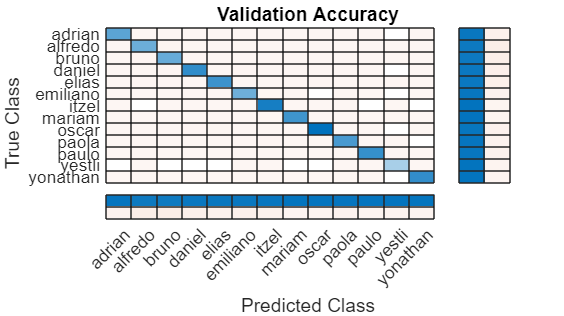


validationPredictions = kfoldPredict(partitionedModel);
figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(labels,validationPredictions,title="Validation Accuracy", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

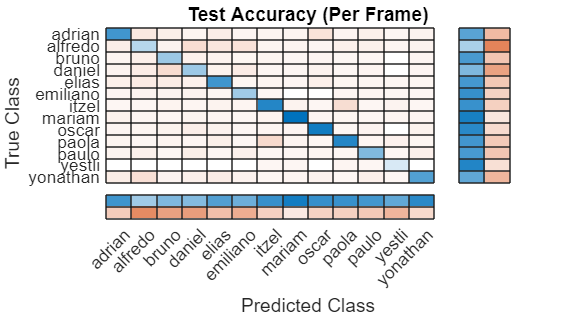

% Pruebas de modelo kNN
features = [];
labels = [];
numVectorsPerFile = [];
while hasdata(adsTest)
    [audioIn,dsInfo] = read(adsTest);
    
    audioIn = audioIn(1:keepLen);

    feat = extract(afe,audioIn);

    isSpeech = feat(:,featureMap.shortTimeEnergy) > energyThreshold;
    isVoiced = feat(:,featureMap.zerocrossrate) < zcrThreshold;

    voicedSpeech = isSpeech & isVoiced;

    feat(~voicedSpeech,:) = [];
    numVec = size(feat,1);
    feat(:,[featureMap.zerocrossrate,featureMap.shortTimeEnergy]) = [];
    
    label = repelem(dsInfo.Label,numVec);
    
    numVectorsPerFile = [numVectorsPerFile,numVec];
    features = [features;feat];
    labels = [labels,label];
end
features = (features-M)./S;

prediction = predict(trainedClassifier,features);
prediction = categorical(string(prediction));

figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(labels(:),prediction,title="Test Accuracy (Per Frame)", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

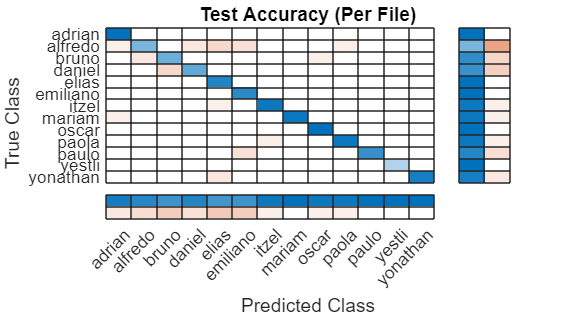


r2 = prediction(1:numel(adsTest.Files));
idx = 1;
for ii = 1:numel(adsTest.Files)
    r2(ii) = mode(prediction(idx:idx+numVectorsPerFile(ii)-1));
    idx = idx + numVectorsPerFile(ii);
end

figure(Units="normalized",Position=[0.4 0.4 0.4 0.4])
confusionchart(adsTest.Labels,r2,title="Test Accuracy (Per File)", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

% Guardado local de variables

save("C:\Users\oscar\OneDrive\Escritorio\sp_seniales\m",'M');
save("C:\Users\oscar\OneDrive\Escritorio\sp_seniales\s",'S');
save("C:\Users\oscar\OneDrive\Escritorio\sp_seniales\trainedClassifier",'trainedClassifier');